# **TU:  Spatial Filter **

**Image Processing with Deep Learning :  Y.-K. Kim**

Mod. 2025.03

## Problem

Create a simple program for spatial filter convolution. 

### Read Image

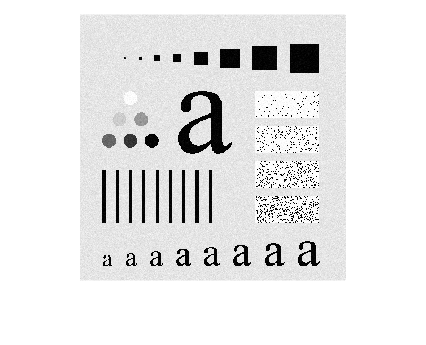

% u,v: image points
% s,t: kernel points
% w: kernel, w(s,t)

% f: source image, f(x,y)

clc; clear; close all;

% image read
f = imread('../../Image/Pattern_original_GaussNoise.tif');
f = rgb2gray(f);

[M, N] = size(f);
figure, imshow(f)

### Filter Kernel Definition

For example: box filter

You may change the filter

% User defined filter window
% You can modify the window

% w =[1 1 1 ;
%     1 1 1 ;
%     1 1 1];

% w =[-1 -1 -1 ;
%     -1 8 -1;
%     -1 -1 -1];

w = ones(21,21);
[wM, wN] = size(w);
wSum = sum(w(:));

if(wSum == 0)
    wSum = 1;
end



### Padding

Example: Padding for 3 x 3 Filter needs to add 1 pixel-sized border on each four sides (Up/Down/Left/Right).

- b = (wM - 1) / 2;    b: yPad

- a = (wN - 1) / 2;    a: xPad

From the original source image  of size  [1: M] x [1: N], 

the new source image (fPad) becomes a bigger size of  [1: M+(2*b)] x [1: N+(2*a)]

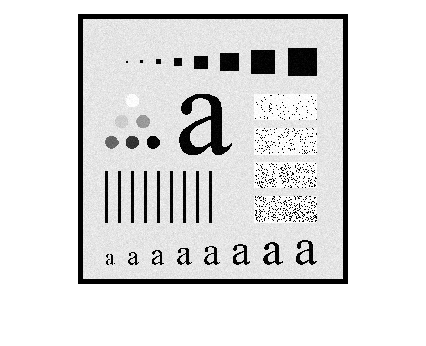


% e.g. 3 x 3 Filter -> pad 1 each side or 2 total
b = (wM - 1) / 2; % b: yPad
a = (wN - 1) / 2; % a: xPad

% fPad image index: [1 to M+(2*b)] x [1 to N+(2*a)]
fPad = zeros(M+2*b,N+2*a); % 2*a size up
fPad(a+1:a+M,b+1:b+N) = double(f); % a+1 -> M 까지, 
figure, imshow(uint8(fPad))

### 2D-convolution (EXERCISE)

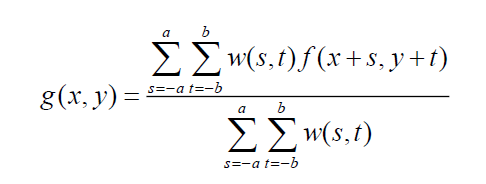

NOTE:  MATLAB index cannot have negative index.

- Index [-a, +a]  should be shifted to  [1, 2*a+1]  by adding (a+1) 

gPad = zeros(size(fPad));

tic
for v = b+1:b+M  
    for u = a+1:a+N
        % convolution of kernel at one point (v,u)
        conv = 0;
        for t = -b:b
            for s = -a:a
                conv = conv + w(t+b+1,s+a+1) * fPad(v+t,u+s);
            end
        end
        gPad(v,u) = conv / wSum;
    end
end
toc

경과 시간은 0.238973초입니다.


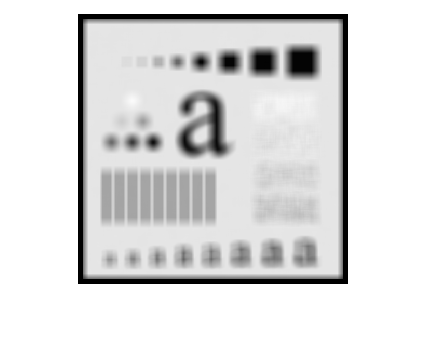

% gPad = gPad + fPad;
figure, imshow(uint8(gPad)) 

### Cropping

Crop the output image to be the same size of the original source image (M,N)

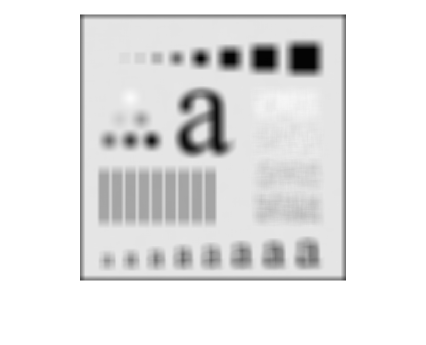

g = gPad(b+1:b+M, a+1:a+N); % cropping

figure, imshow(uint8(g)) 